# Kinematics, Dynamics and Controls

## Homework 2

**Part 1:** Derive dynamic equations using Euler-Lagrange toolbox from MATLAB

clear;
clc;
addpath('./trajOptim/tools');
addpath('./trajOptim');

syms theta(t) dtheta x(t) dx t l m_cart m_body g F
position = [1 0 0 x; 0 1 0 0; 0 0 1 0; 0 0 0 1]*...
    [cos(theta) -sin(theta) 0 0; sin(theta) cos(theta) 0 0; 0 0 1 0; 0 0 0 1]*...
    [1 0 0 0; 0 1 0 l; 0 0 1 0; 0 0 0 1];

dposition = diff(position,t);
dposition = subs(dposition, diff(theta(t),t), dtheta);
dposition = subs(dposition, diff(x(t),t), dx);

T = position\dposition;
syms theta dtheta x dx 

%% Take T_new from elements of T. 
%% Doing this because T from above equations comes as sym function with one element 
%% and not as matrix of symbolic functions
T_new = [0, -dtheta, 0, -(dtheta*l*cos(theta)^2 - dx*cos(theta) + dtheta*l*sin(theta)^2)/(cos(theta)^2 + sin(theta)^2);
    dtheta, 0, 0, -(dx*sin(theta))/(cos(theta)^2 + sin(theta)^2);
    0, 0, 0, 0; 0, 0, 0, 0];
g_vector = simplify(vectorFromTwist(T_new));

g_vector = [g_vector(4:5),g_vector(3)];
g_vector_trans = [g_vector(1);g_vector(2);g_vector(3)];

m_matrix = [m_body 0 0; 0 m_body 0; 0 0 0]; % no inertia terms

L = 0.5*m_cart*dx^2 + 0.5*g_vector*m_matrix*g_vector_trans...
    -m_body*g*l*cos(theta); % Lagrangian
Euler_Lagrange = simplify(L)

$$Euler\_Lagrange = \frac{{\mathrm{dx}}^{2}\,m_{\mathrm{body}}}{2}+\frac{{\mathrm{dx}}^{2}\,m_{\mathrm{cart}}}{2}+\frac{{\mathrm{dtheta}}^{2}\,l^{2}\,m_{\mathrm{body}}}{2}-g\,l\,m_{\mathrm{body}}\,\cos\left(\theta \right)-\mathrm{dtheta}\,\mathrm{dx}\,l\,m_{\mathrm{body}}\,\cos\left(\theta \right)$$

X = {x dx theta dtheta}; % Vector of generalized coordinates %X = {q1 dq1 q2 dq2 ...}
Q_i = {0 0}; Q_e = {F 0}; % No generalized forces
R = 0; % Friction term
par = {g m_cart m_body l}; % System parameters
% Create symbolic differential equations …
VF = EulerLagrange(L,X,Q_i,Q_e,R,par);

Dynamic_Equations = simplify(VF)

$$Dynamic\_Equations = \begin{array}{l} \left(\begin{array}{c} \mathrm{dx}\\ \frac{-l\,m_{\mathrm{body}}\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+F+g\,m_{\mathrm{body}}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sigma_{1}}\\ \mathrm{dtheta}\\ \frac{-l\,m_{\mathrm{body}}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+F\,\cos\left(\theta \right)+g\,m_{\mathrm{body}}\,\sin\left(\theta \right)+g\,m_{\mathrm{cart}}\,\sin\left(\theta \right)}{l\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-m_{\mathrm{body}}\,{\cos\left(\theta \right)}^{2}+m_{\mathrm{body}}+m_{\mathrm{cart}} \end{array}$$

**Part 2: Simulink Model**

open_system('cartPole');

**Part 3: Manual Pole placement to find linear feedback controller**

A_time = jacobian(VF,[x dx theta dtheta]);
B_time = jacobian(VF, F);
A_lin = subs(A_time, [theta x dtheta dx], [0 0 0 0]);
B_lin = subs(B_time, [theta x dtheta dx], [0 0 0 0]);

g = 9.81;
m_cart = 1;
m_body = 0.1;
l = 1;
A = eval(A_lin);
B = eval(B_lin);

gravity = g;
m_c = m_cart;
m_b = m_body;
l_pend = l;

poles = [-2 -3 -4 -5];
feedbackGain = -place(A, B, poles)

feedbackGain =    12.2324   15.6983  -94.0234  -29.6983



% Initial states
x_initial = 0;
dx_initial = 0; 
theta_initial = 0.3;
dtheta_initial = 0;

**Part 4: LQR controller**

Q = [1 0 0 0; 0 1 0 0;
    0 0 100 0; 0 0 0 1];
R = 0.1;

feedbackGain = -lqr(A,B,Q,R)

feedbackGain =     3.1623    6.8378  -67.8026  -19.0559



% Initial states
x_initial = 0;
dx_initial = 0; 
theta_initial = 1.5;
dtheta_initial = 0;


**Part 5: Non Linear feedback controller**

% syms ddx force E_pend
% E_pend = 0.5*g_vector*m_matrix*g_vector_trans...
%     -m_body*g*l*cos(theta)

$$ans = -\frac{981\,\cos\left(\theta \right)}{1000}$$

% E_desired = 1;
% 
% ddx = k_E*dtheta*cos(theta)*
% force = (m_body + m_cart - m_body*cos(theta)^2)*ddx - g*m_body*sin(theta)*cos(theta) + l*m_body*dtheta^2*sin(theta)


k_E = 3;
kp = 5;
kd = 0.0;
x_initial = 0;
dx_initial = 0; 
theta_initial = 0.8*pi;
dtheta_initial = 0;
Energy_desired = m_b*gravity*l_pend*(1-cos(theta_initial))

Energy_desired = 1.7746

**Part 6**

   --> Install Chebfun toolbox:  (http://www.chebfun.org/)
   --> Running with default method instead ('trapezoid')
~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
Running OptimTraj, iteration 1
  -> Transcription via trapezoid method, nGrid = 30

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     153    0.000000e+00    6.757e-01    5.235e-11
    1     306    2.951446e+02    5.798e-01    1.476e+02    6.948e+01
    2     459    2.966142e+02    5.601e-01    1.483e+02    5.889e-01
    3     612    2.630483e+02    1.564e-01    1.315e+02    1.595e+01
    4     765    2.290240e+02    2.830e-02    1.145e+02    1.369e+01
    5     918    1.807672e+02    2.520e-02    9.038e+01    8.760e+00
    6    1071    1.676325e+02    1.292e-02    2.934e+01    8.793e+00
    7    1224    1.571778e+02    1.367e-02    2.697e+01    8.963e+00
    8    1377    1.534391e+02    8.562e-03    2.449e+01    5.341

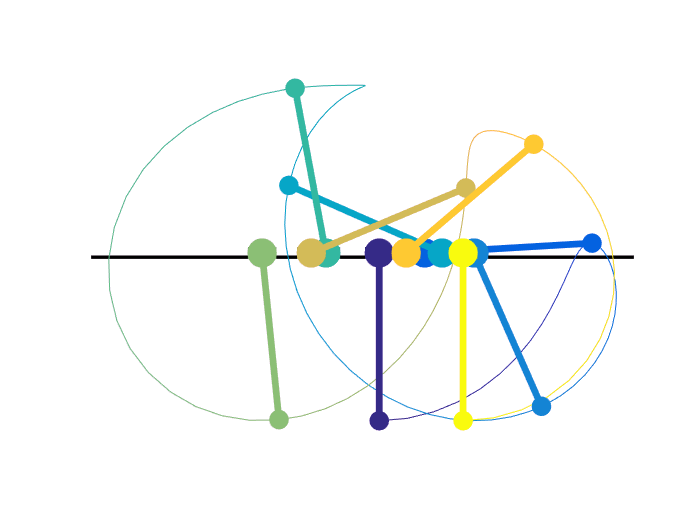

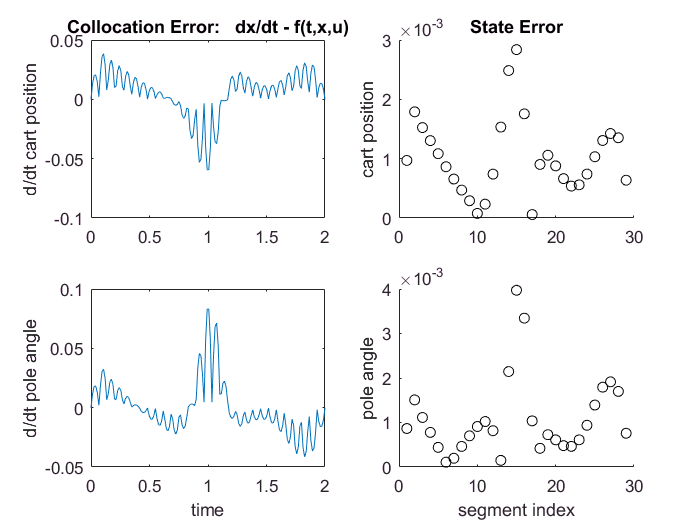

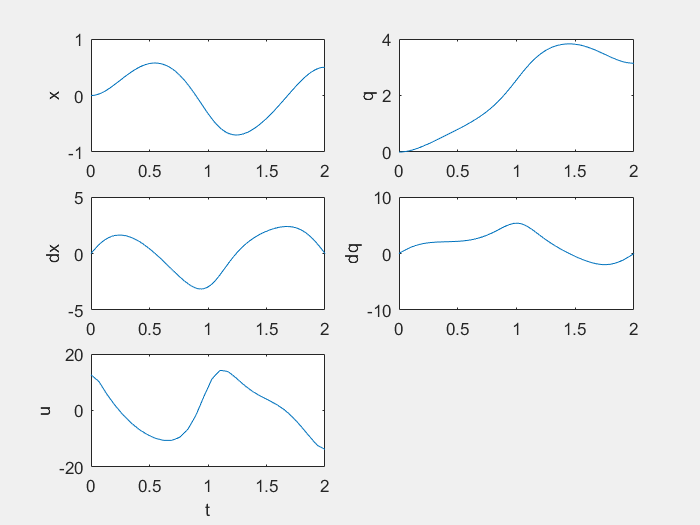

% input = timeseries(u,0:4/149:4);
MAIN_minForce();

input = u;
% VF_solve = eval(VF);
x_initial = 0;
dx_initial = 0; 
theta_initial = pi;
dtheta_initial = 0;
